# Machine Learning with MATLAB 

Digital Twin & Automation

# Logistic Regression

## Binary linear classifier

`Method 1:`fitclinear()

- For two-class (binary) learning with **high-dimensional**, full or sparse predictor data. 

`Method 2:`fitglm()

- For low- through medium-dimensional predictor data sets, see [Alternatives for Lower-Dimensional Data](https://www.mathworks.com/help/releases/R2021b/stats/fitclinear.html#mw_d1b0a02e-0dfa-4c0e-bb4d-e6859309ec45)

## **Example 1: Logistic Regression**

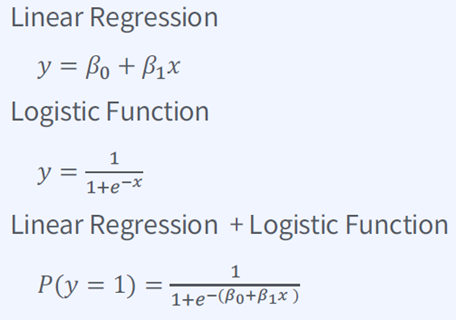

**Data Acquisition** 

clear
load fisheriris
X = meas(:,1:2);            % Use two features (x1, x2) for fitting
sp = categorical(species);
Ystat=sp=='setosa';         % Binary classfication:  setosa vs no-setosa


**Classification: **Logistic Regression 

Mdl = fitclinear(X,Ystat,'Learner','logistic')

Mdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'logit'
              Beta: [2×1 double]
              Bias: 8.3233
            Lambda: 0.0067
           Learner: 'logistic'


  Properties, Methods


**Plot**  Logistic Regression of Train data:  z vs Logistic Function

- z= b0+b1X1+b2X2

- y=1/(1+exp(-z))

% Plot z vs Y=sigmoid(z)
z=Mdl.Bias+X*Mdl.Beta;

%%% YOUR CODE GOES HERE
% Y=________________;  % Logistic function


Y1indx=find(sp=='setosa')

Y1indx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Y0indx=find(sp~='setosa')

Y0indx =     51
    52
    53
    54
    55
    56
    57
    58
    59
    60


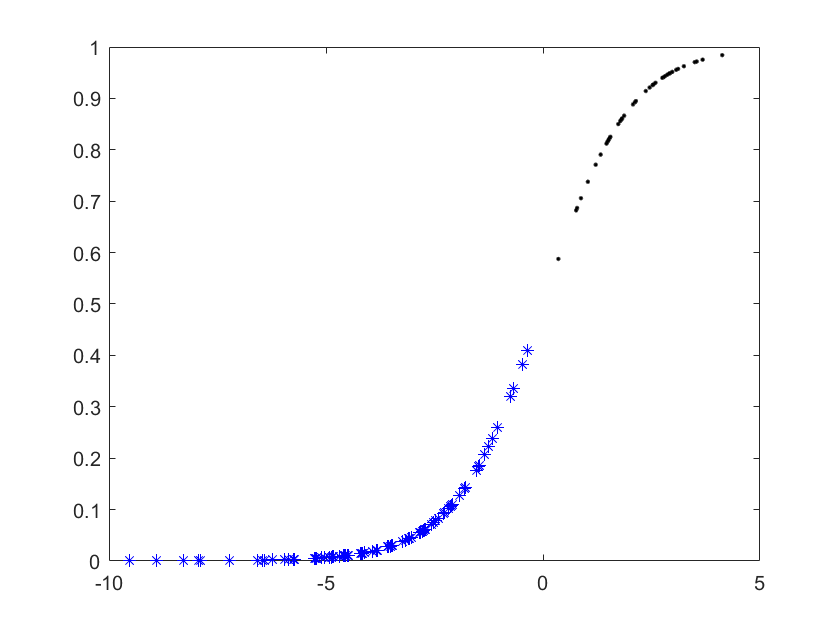



figure
plot(z(Y1indx),Y(Y1indx),'k.')
hold on
plot(z(Y0indx),Y(Y0indx),'b*')
hold off

#### Cross-validation (k-fold)

Construct a cross-validated classifier from the model.

cvMdl = fitclinear(X,Ystat,'Learner','logistic', 'KFold',5)

cvMdl =   ClassificationPartitionedLinear
    CrossValidatedModel: 'Linear'
           ResponseName: 'Y'
        NumObservations: 150
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


Examine the cross-validation loss, which is the average loss of each cross-validation model when predicting on data that is not used for training.

kloss = kfoldLoss(cvMdl)

kloss = 0

**Test **  

% an average flower feature values
flwr = mean(X); 
flwr2 = mean(X(1:10,:)); 
Xtest=flwr2;

% Convert TestData as Logistic Function
ztest=Mdl.Bias+Xtest*Mdl.Beta;
%%% YOUR CODE GOES HERE
% Ytest=____________

Ytest = 0.9114


flwrClass = predict(Mdl,Xtest)

flwrClass = logical
   1


# Exercise

## Exercise 1:  CWRU dataset

Apply logistic regression to classifiy   outer or  inner bearing fault  

### Dataset 

- Given dataset contains many features extracted from CWRU dataset

- For binary class:  Outer and Inner Race Fault

clear

% Class 'Inner', 'Outer'
load("../CWRU_dataset/CWRU_features/example_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));

Ytrain = class_cwru_train;       % fault class
classKeep = ~strcmp(Ytrain,'normal');  % eliminate normal class
X = Xtrain(classKeep,:);
Y = Ytrain(classKeep);


% Plot features 
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

**Classify using Logistic Regression and Analyze **

% Your code goes here
% Your code goes here

**Predict  test data and Analyze**

% Class 'Inner', 'Outer'
load("../CWRU_dataset/CWRU_features/example_test.mat");

% Your code goes here
% Your code goes here

## Exercise 2

**Use gradient descent to obtain optimal parameters of Logistic Regression**

**Cost function**

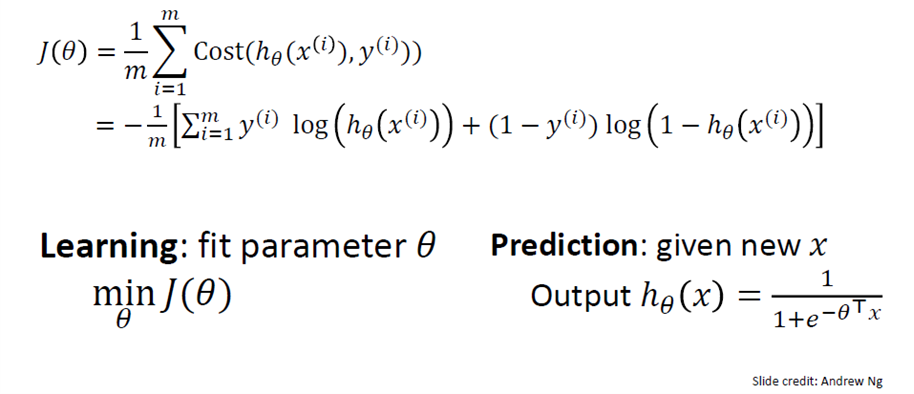

**Gradient Descent**

 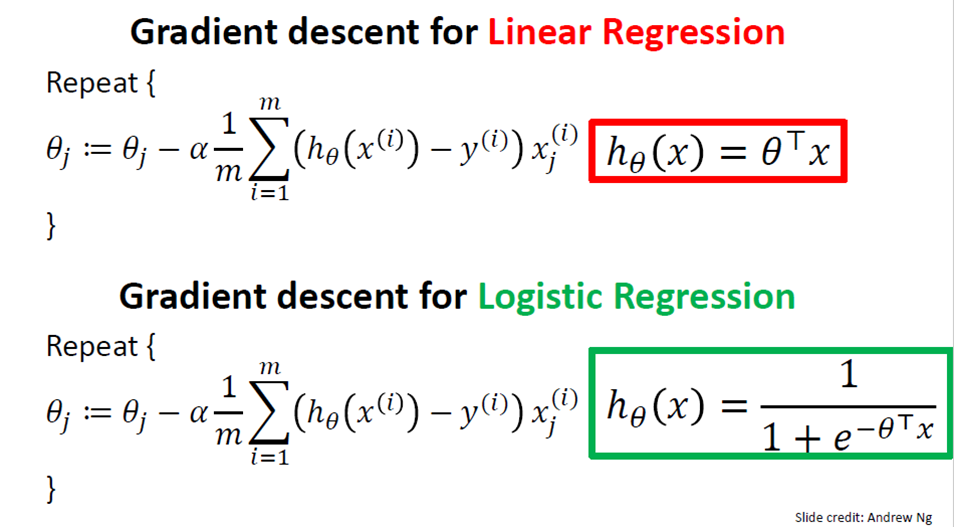

% Your code goes here
% Your code goes here
% Your code goes here